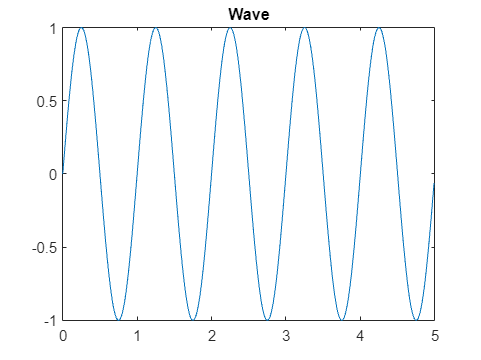


Ta = 0.01; %question asks for Ta = 0.2, but its doenst become a good model wave
t = [0:Ta:5-Ta];
x = sin(2*pi*t);

figure(1);

plot(t,x)
title('Wave')
hold on

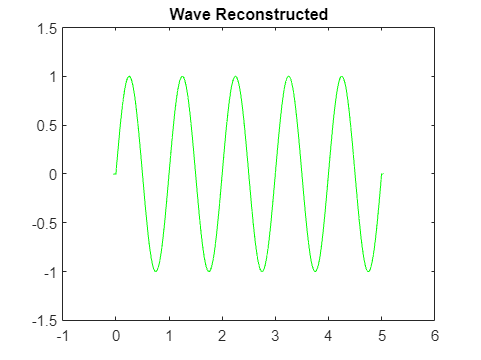



[Y,Ty] = ReconstroiSinal(x,Ta);
figure(3)
plot(Ty,Y,'g')
title('Wave Reconstructed')

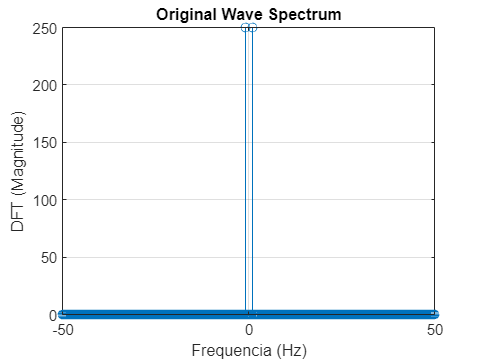



Espetro(x,Ta);
title('Original Wave Spectrum')

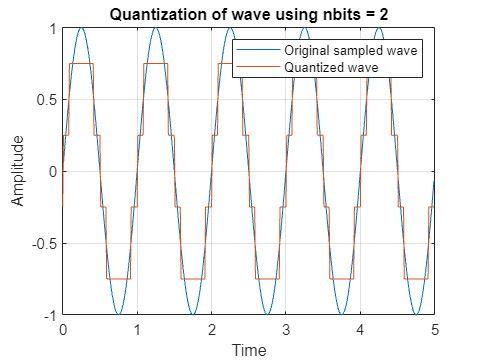

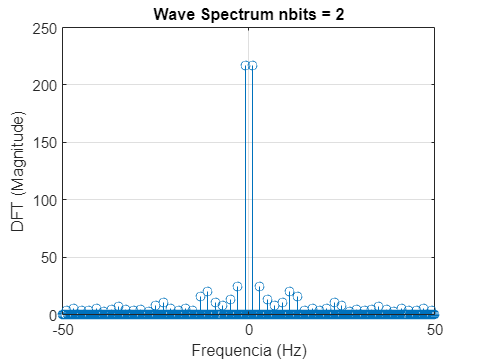

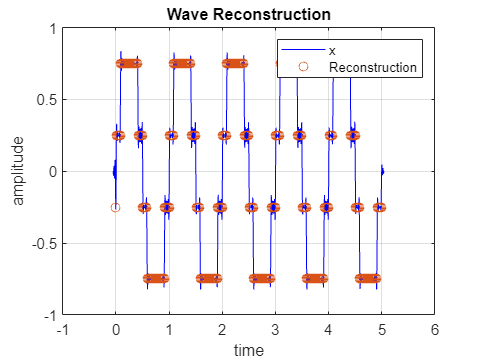

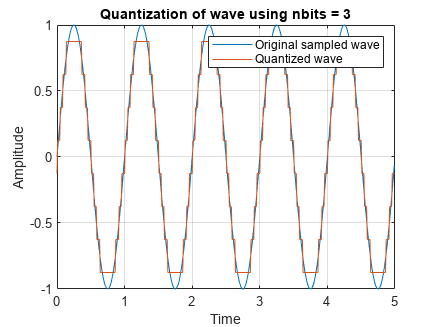

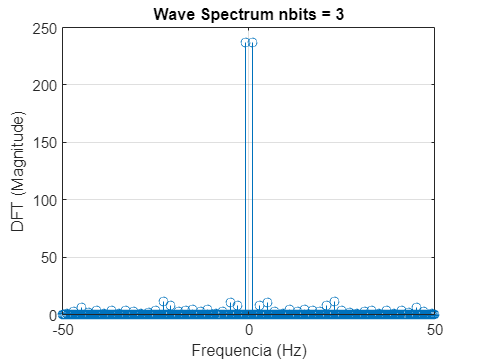

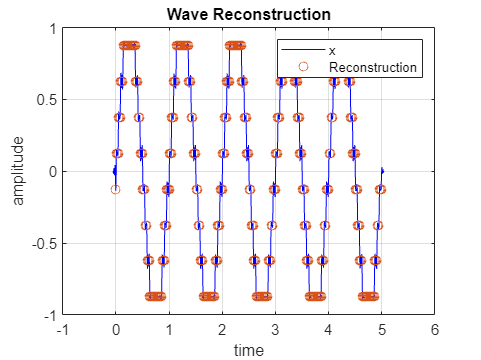

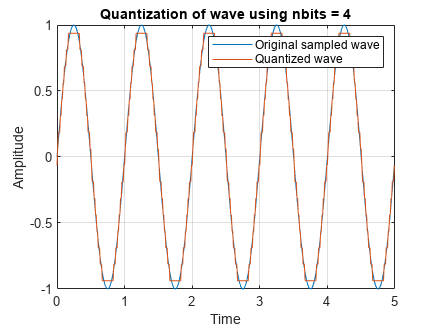

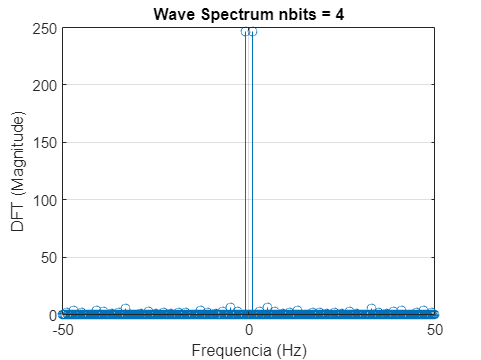


%the bigger the bitsize, the closer to the original wave it becomes

for nbits = [2,3,4]
    Npal = 2^nbits;
    amp = max(x);
    delta = amp/Npal;

    partition = -amp + delta*2 : delta*2 : amp - delta*2;
    codebook = -amp+delta : delta*2 : amp-delta;

    [~,quantz] = quantiz(x,partition,codebook);

    figure
    plot(t,x)
    hold on
    plot(t,quantz)
    hold off
    grid on
    xlabel('Time')
    ylabel('Amplitude')
    legend('Original sampled wave','Quantized wave');
    title("Quantization of wave using nbits = " + nbits)


  %%
  figure
  Espetro(quantz,Ta);
  title("Wave Spectrum nbits = " + nbits)

  %%
  figure
  ReconstroiSinal(quantz,Ta);
end